# Lab book - pRF mapping (training)

**Location**: Neurophysiology lab (B1A19)

**Equipment**: SCNI red rig - MRI test setup 

- Bevil chair attached to 80/20 metal bars in the red rig

- LG Ultra HD 27'' 8MP IPS display (LG 27HJ712C-W)

- Red rig default Eyelink 2 camera mounted on 3D printed goggles with hot mirror

- Copper juice tube taped on large diameter loc-line tube

- Reward delivery system set at 1 psi

- Total reward volume: 150 mL water + 100 mL apple juice

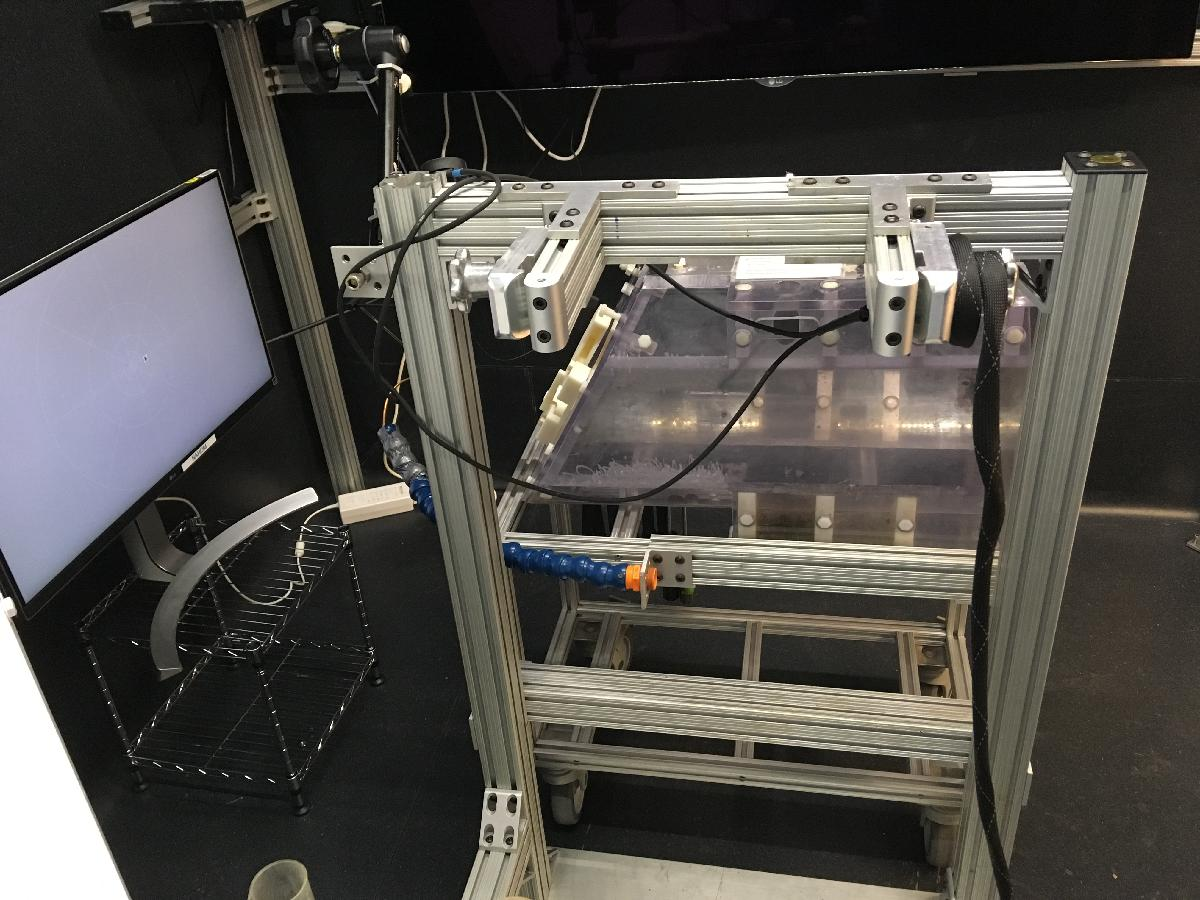   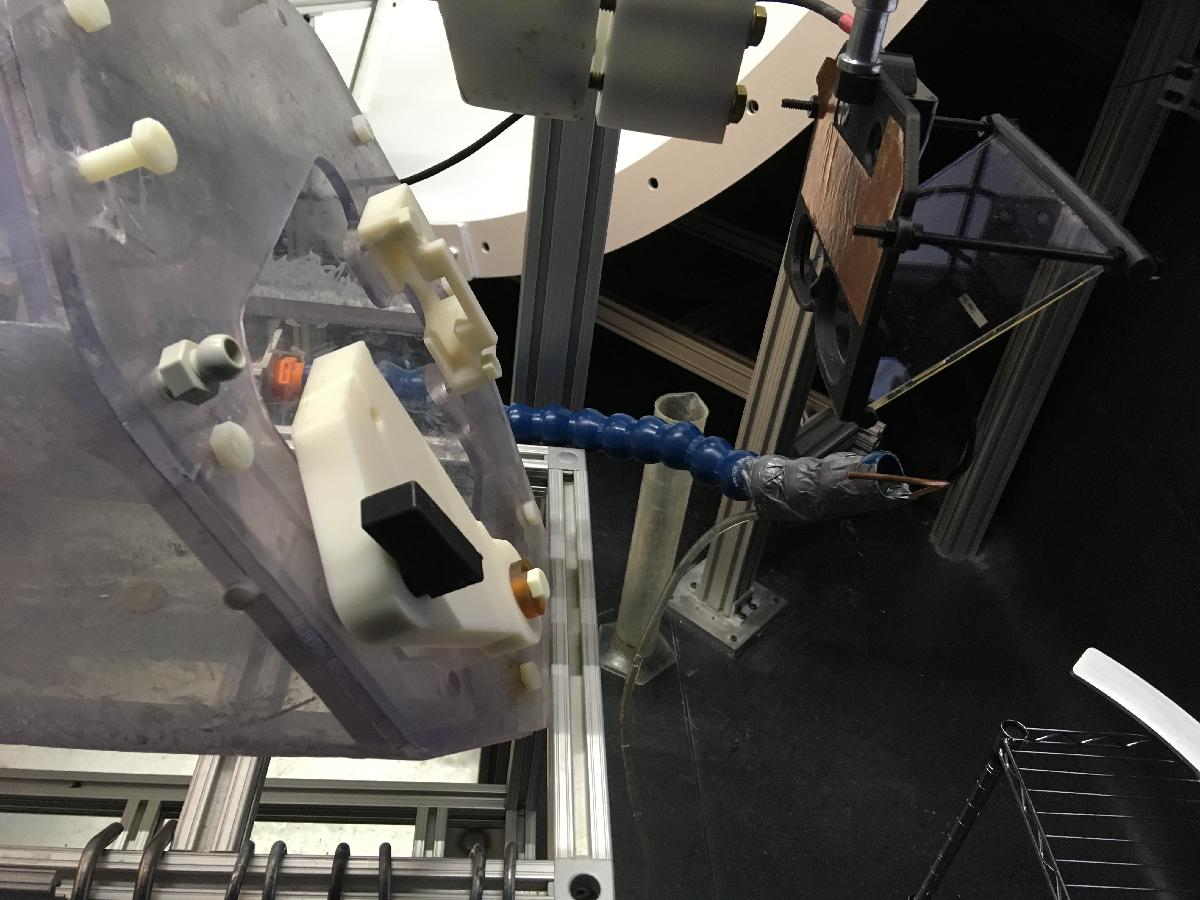

**Session details**:

subjectID = 'Francois';
load(['/Users/ocakb2/Library/Mobile Documents/com~apple~CloudDocs/Github/pRF_mapping/results/' subjectID '/all_sessions.mat']);
session = day13;
load(['/Users/ocakb2/Library/Mobile Documents/com~apple~CloudDocs/Github/pRF_mapping/results/' subjectID '/20200911/calibration_run8.mat']);
fullDate = [str2double(session.date(1:4)) str2double(session.date(5:6)) str2double(session.date(7:8))];
fprintf('Date:              %s', datestr(datenum(fullDate),22));

Date:              Sep.11,2020

fprintf('Start time:       %s', datestr(datenum([fullDate str2double(session.startTime(1:2)) str2double(session.startTime(3:4)) str2double(session.startTime(5:6))]),14));

Start time:        1:05:06 PM

fprintf('End time:         %s', datestr(datenum([fullDate str2double(session.endTime(1:2)) str2double(session.endTime(3:4)) str2double(session.endTime(5:6))]),14));

End time:          1:59:41 PM

fprintf('Display size:      %.1f x %.1f cm', params.monitorSize(1), params.monitorSize(2));

Display size:      59.9 x 34.0 cm

fprintf('Viewing distance:  %.1f cm', params.viewingDistance);

Viewing distance:  52.0 cm

fprintf('Stimulus size:     %.2f degrees', round(params.stimSize/params.pixPerDeg(1),2));

Stimulus size:     37.12 degrees

fprintf('Fix. dot size:     %.2f degrees', round(params.fixDotSize/params.pixPerDeg(1),2));

Fix. dot size:     0.26 degrees

fprintf(['Observations:\n' session.comments]);

Observations:
The animal is motivated to do the task (long fixations for up to 2 min) but gets frustated when the reward volume goes to baseline 
(because of a fixation break). He then stops looking at the fixation dot until the end of the run. Drank 250 mL over the session.

disp(struct2table(rmfield(session, {'subjectID' 'date' 'startTime' 'endTime' 'comments'})));

    runNum    duration    numTrials    numRewards    performance    fixWindowSize    fixBreakTolerance    stimDuration    isiDuration
    ______    ________    _________    __________    ___________    _____________    _________________    ____________    ___________

      1         300.1        229          200          87.336             4                 0.6               1.3              0     
      2        304.46        231          143          61.905             4                 0.6               1.3              0     
      3        297.88        226          104          46.018             4                 0.6               1.3              0     
      4        309.75  

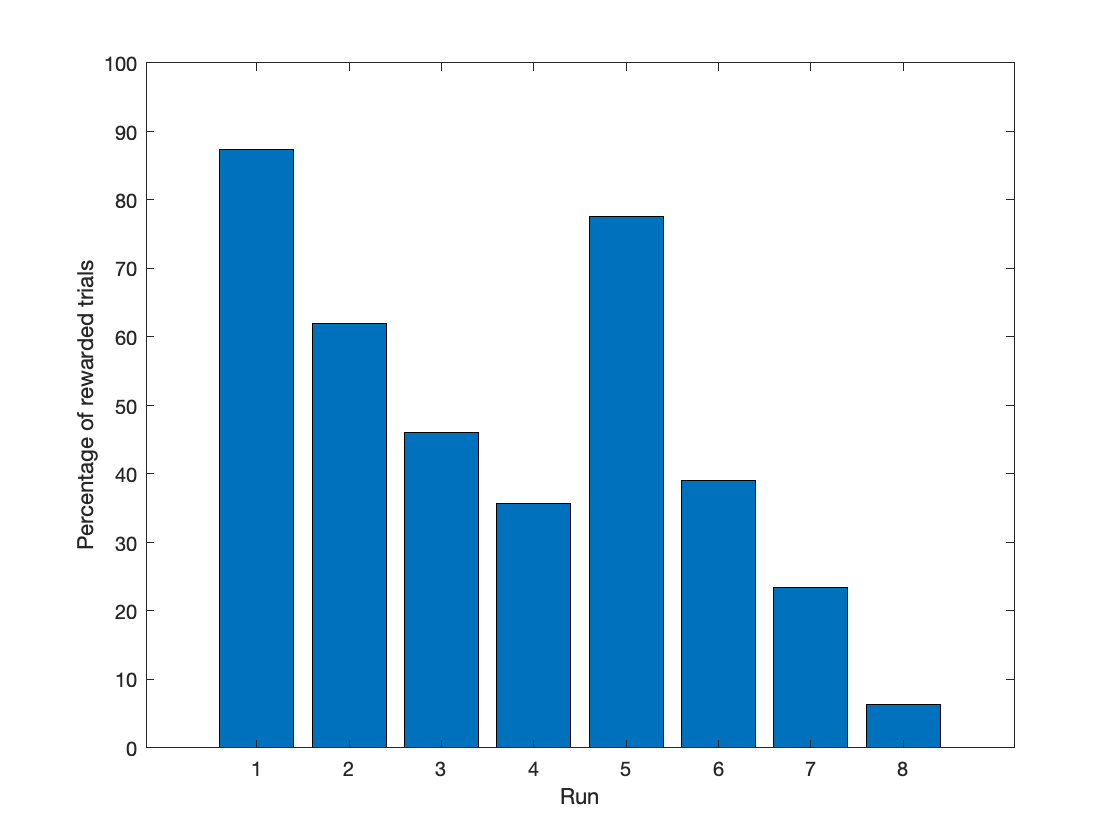

bar(1:length(session.performance)-1, session.performance(1:length(session.performance)-1));
ylim([0 100]);
xlabel('Run');
ylabel('Percentage of rewarded trials');